# Tutorial: Reflectance Modeling

This software is made available under the MIT license. See SONIC/LICENSE for details.

This tutorial will demonstrate how to use reflectance models available under the `sonic.Reflectance` class. Reflectance models describe light reflection on a surface based on material properties along with observer and light source directions. Reflectance modeling is used throughout OPNAV to render imagery of celestial bodies and terrain. 

The objective is twofold. The first is to provide users with a guide on the available reflectance models through the generation of bidirectional reflectance distribution function (BRDF) curves for a given experimental setup. The secondary objective is to highlight the differences between all the reflectance models in `sonic.`

## Background and Setup

Reflectance models in `sonic` are divided into two functions: reflectance model instantiation and BRDF calculation. 

For each reflectance model, an object can be created by calling the constructor with the model-specific constants as inputs, while the BRDF values can be calculated using the `refl` function with the surface, observer and light source direction inputs. The typical reflectance model architecture is shown below. 

`    reflObj = sonic.reflClass(modelInput1, modelInput2, ...)`

`    BRDFValues = reflObj.refl(inputType, var1, var2, var3)`

Model parameters (shown as `modelInput` above) like albedo are specific to each reflectance model and will be discussed in the subsequent sections. 

Reflectance models require representations of the surface normal, light source and observer directions, whether that be via angles or vectors. Each `reflObj.refl` function allows for three different methods of representing the direction:

- `inputType`: "iep"

                var1: incidence angles, `i`

                var2: emission angles, `e`

                var3: phase angles, `g`

- `inputType`: "iea"

                `var1`: incidence angles, `i`

                `var2`: emission angles, `e`

                `var3`: emission azimuth angles, `phi`

- `inputType`: "ien" 

                `var1`: incidence vectors, `u_i`

                `var2`: emission vectors, `u_e`

                `var3`: surface normal vectors, `u_n`

where all angles in "iea" and "iep" are in radians and of size `(n, m)` and all vectors in "ien" are `(3, n)`. Incidence and emission angles are the zenith angles measured from the surface normal and must be [0, pi/2]. The phase angle is measured between the incidence and emission vector and must be [0, pi]. The emission azimuth angle is the planar angle of the emission vector measured from the plane of incidence. The azimuth angle must be betwen [0, pi]. 

Note: `var3` is always required for "ien", but is not always required for "iep" and "iea" inputs based on the reflectance model.

### Experimental Setup

Suppose you are in orbit around an asteroid. There is a point on a surface that is illuminated at an incidence angle `i`. You would like to calculate the BRDF curve as you orbit. As an observer, you will likely span emission angles `e` between [-pi/2, pi/2]. Reflectance models only allow for an emission angle between [0, pi/2]. As such, you must use the azimuth angle `phi = pi`  when `e` is negative to help represent the [-pi/2, 0] emission angle range. You can generate this experimental setup with the following code.

% Number of points
n = 100;

% Set emission angle to span [-pi/2, pi/2]
e = linspace(-pi/2, pi/2, n);

% Set incidence angle to be constant
inc = 75*pi/180;
i = inc*ones(1, length(e));

% Set emission azimuth angles to 0 or pi if e < 0
phi = zeros(1, length(e));
l = e < 0;
phi(l) = pi;

% Take the absolute value of e to satisfy the emission angle requirements
e = abs(e);


## Reflectance Models

The following sections will cover reflectance model inputs and generate the BRDF curves using the provided experimental setup. More detailed descriptions of the inputs and outputs for each function are provided in the function headers in each reflectance model file.

### Lambert

The Lambert reflectance model is the simplest reflectance model in `sonic` because the BRDF is constant. The Lambert reflectance model only requires one model-specific parameter: albedo. Variable albedo for each point can be provided as an `(n, m)` matrix that is consistent with other inputs, however we will use a scalar for simplicity. Additionally, the Lambert model does not require the third azmith input because it is not needed for the BRDF calculation, but may be input to check input compatibility.

AL_lam = .25/4;

lam = sonic.Lambert(AL_lam);
brdfLambert = lam.refl("iea", i, e, phi);

### Lommel-Seeliger

The Lommel-Seeliger reflectance model is one of the simplest models derived from radiative transfer theory and is often used for low-albedo systems. The Lommel-Seeliger reflectance model inputs are similar to `sonic.Lambert` with one key difference. Rather than enter the albedo, users must input the single-scattering albedo. Like the Lambert model, `var3` is not required for the "iea" and "iep" `inputType`.

AL_ss_LS = .25;

LS = sonic.LommelSeeliger(AL_ss_LS);
brdfLS = LS.refl("iea", i, e, phi);

### LunarLambert

The LunarLambert model takes a weighted combination of the Lambert and Lommel-Seeliger models. A phase angle-dependent function is used as the weighting. In addition to albdeo, `sonic.LunarLambert` requires a `modelType` input which offers a choice between three phase function inputs:

- `GaskellApprox`: Gaskell's phase function approximation used in sterophotoclinometry (SPC),

- `McEwenCubic`: McEwen's cubic phase function for the Moon

- `polyPhase`: User-defined polynomial phase function

`GaskellApprox and McEwenCubic `do not require any additional inputs. Upon choosing `polyPhase,` you must also include a `coeffs` input as a 3D matrix of coefficients of size `(n, m, k)` where `(n, m)` represents the size of the inputs and `k` is the dimension of the polynomial. You may also choose to input one polynomial to be used for all points by entering `(1, 1, k).`  Enter a scalar value to use generate a phase-independent lunar-Lambert BRDF. Note that all polynomial coefficients must be entered in ascending order. 

Since the lunar-Lambert reflectance model weighs both Lambert and Lommel-Seeliger reflectance, the albedo encompasses both Lambertian albedo and single-scattering albedo, and is also a function of phase. As such, the same polynomial input scheme can be applied to albedo. To see an example of `polyPhase,` please read the Tutorial on OrthoSphere Rendering with Reflectance Models.

Rather than generate a random polynomial for this experiment, we will use Gaskell's phase function approximation with a constant, scalar albedo for better reflectance model comparison.

AL = AL_ss_LS/8;

LL = sonic.LunarLambert(AL, "GaskellApprox");
brdfLL = LL.refl("iea", i, e, phi);

### Chandrasekhar

The Chandrasekhar reflectance model is a more advanced reflectance model derived from radiative transfer theory. This model utilizes albedo and the Chandrasekhar H-Function to calculate the BRDF. Like all other reflectance models, the albedo can be (n, m). Additionally, the H-Function calculation method is determined by the `HFuncType` input. 

`HFuncType` may be 'exact', 'linear', or 'rational'. The 'exact' method approximates the H-Function by calculating the recursive integral while the  'linear' and 'rational' approximations utilizes Hapke's  respective approximations.

CS = sonic.Chandrasekhar(AL_ss_LS, 'exact');
brdfCS = CS.refl("iea", i, e, phi);

### Hapke

The Hapke reflectance model encompasses both the basic isotropic multiple scattering approximation (IMSA) and modified IMSA (MIMSA) models through the `hapkeModelType` input. Since the Hapke model also uses Chandrasekhar's H-Function in the BRDF calculation, the `HFuncType` input provides the same options as in `sonic.Chandrasekhar.` Hapke also requires a single-scattering phase function (SSPF) for the BRDF calculation. Options for `SSPF` include "isotropic", "Rayleigh", or "HG1" (Henyey-Greenstein, one-sided). If you use "HG1", you must also input the scattering parameter, `xi`. 

As in all reflectance models, albedo may be `(n, m)` so long as it matches the other input dimensions.

xi = -.1;

H = sonic.Hapke(AL_ss_LS, 'IMSA', 'linear', 'HG1', xi);
brdfH = H.refl("iea", i, e, phi);

### Oren-Nayar

The Oren-Nayar is the only rough surface reflectance model currently supported in `sonic`. A rough surface reflectance model includes surface deviations into account when calculating the total reflectance. Besides albedo, `sonic.OrenNayar` requires a roughness parameter, `sigma`, as an input. `Sigma` must be [0, 1] rad and must be of size `(n, m)`. A third, optional input is `calcInterrefl`, a logical input that offers users a choice between calculating the interreflection component of reflectance. By default, `calcInterrefl` is `false`.

sigma = 1;

ON = sonic.OrenNayar(AL_lam, sigma, 1);
brdfON = ON.refl("iea", i, e, phi);

## Model Comparison

To plot the various BRDF curves, reset the emission angles to their original span [-pi/2, pi/2].

e_plot = e;
e_plot(l) = -e(l);
e_plot = e_plot*180/pi;

Use e_plot and all BRDF curves to plot the model comparison.

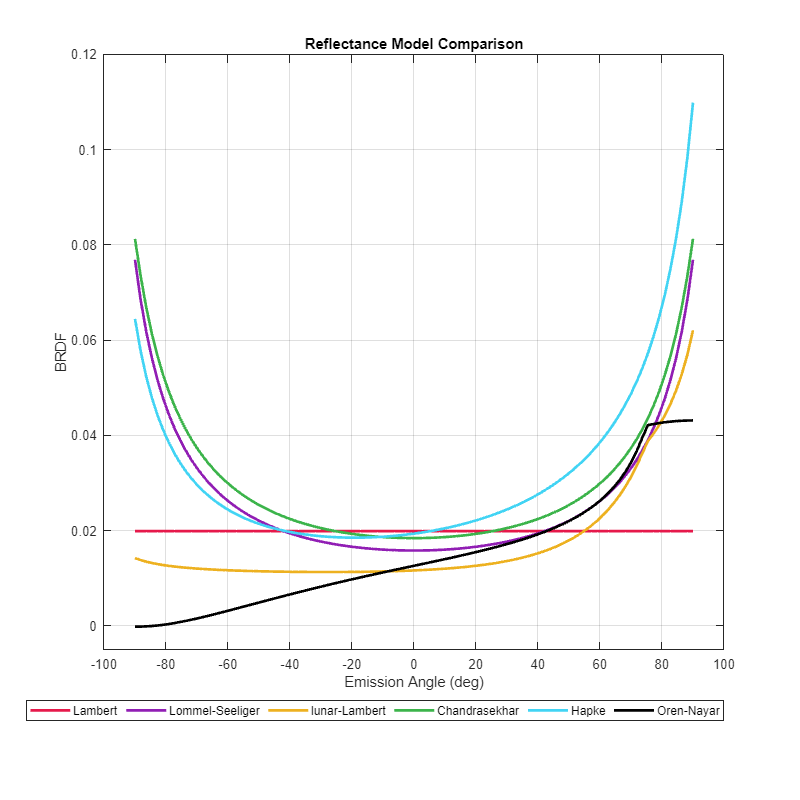

figure('Position', [10 10 900 900])
plot(e_plot, brdfLambert, 'DisplayName', 'Lambert', 'LineWidth', 2, 'Color', '#e6194B')
hold on
plot(e_plot, brdfLS, 'DisplayName', 'Lommel-Seeliger', 'LineWidth', 2, 'Color', '#911eb4')
plot(e_plot, brdfLL, 'DisplayName', 'lunar-Lambert', 'LineWidth', 2, 'Color', "#EDB120")
plot(e_plot, brdfCS, 'DisplayName', 'Chandrasekhar', 'LineWidth', 2, 'Color', '#3cb44b')
plot(e_plot, brdfH,  'DisplayName', 'Hapke', 'LineWidth', 2, 'Color', '#42d4f4')
plot(e_plot, brdfON,  'DisplayName', 'Oren-Nayar', 'LineWidth', 2, 'Color', '#000000')
hold off
xlabel('Emission Angle (deg)')
ylabel('BRDF')
title('Reflectance Model Comparison')
legend('Location', 'southoutside', 'Orientation', 'horizontal')
grid on

xlim([-100 100])
ylim([-0.005 0.1200])